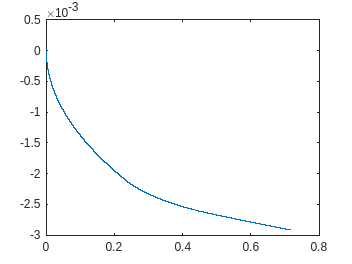

clc; clear all; close all;

% This is Hydraulic System number 5 . rho (density) = 875 kg/m^3 . beta (bulk modulus) = 1100 MPa . Minimum gauge pressure (vacuum) = -1 bar , ps1 = 191 bar , ps02 = 140 bar , V1 = 649 cm^3 , V2 = 947 cm^3 , V3 = 546 cm^3 , Cd1 = 0.52 , Ad1 = 38 mm^2 , Cd2 = 0.52 , Ad2 = 38 mm^2 , Cd3 = 0.83 , Ad03 = 20 mm^2 , Cd4 = 0.80 , Ad4 = 38 mm^2 , Cd5 = 0.63 , Ad5 = 33 mm^2 , Cd6 = 0.68 , Ad6 = 29 mm^2 , tRU1 = 239 milliSeconds , p1 (initial value) = 0 bar , p2 (initial value) = 0 bar , p3 (initial value) = 0 bar , simulation time = 717 milliSeconds . What is the maximum absolute value of the flow in orifice 5 [l/min] ?

rho = 875; % kg/m^3
beta = 1100*10^6; % Pa

gauge_min = -1*10^5; % Pa

ps1 = 191*10^5; % Pa
ps02 = 140*10^5; % Pa
V1 = 649/10^6; % m^3
V2 = 947*10^6; % m^3
V3 = 546*10^6; % m^3
Cd1 = 0.52;
Ad1 = 38*10^-6; % m^2
Cd2 = 0.52;
Ad2 = 38*10^-6; % m^2
Cd3 = 0.83;
Ad03 = 20*10^-6; % m^2
Cd4 = 0.8;
Ad4 = 38*10^-6; % m^2
Cd5 = 0.63;
Ad5 = 33*10^-6; % m^2
Cd6 = 0.68;
Ad6 = 29*10^-6; % m^2

tRU1 = 239/1000; % s
p1 = 0;
p2 = 0;
p3 = 0;

simTime = 717/1000; % s
t = 0; % s
idx = 1;
dt = 10^-5;

while(t < simTime)
    % Calculation
    if(t<tRU1)
    ps2 = 0;
    elseif(t < 2*tRU1)
        ps2 = ps02*(t-tRU1)/tRU1;
    else
        ps2 = ps02;
    end
    
    if(t <= tRU1)
        Ad3 = Ad03;
    elseif(t <= 2*tRU1)
        tm = t-(tRU1);
        Ad3 = Ad03 * (1-(tm/tRU1));
    else
        Ad3 = 0;
    end

    Q1 = Cd1 * Ad1 * sign(p1-p3) * sqrt(2/rho * abs(p1-p3));
    Q2 = Cd2 * Ad2 * sign(ps1-p1) * sqrt(2/rho * abs(ps1-p1));
    Q3 = Cd3 * Ad3 * sign(p3-gauge_min) * sqrt(2/rho * abs(p3-gauge_min));
    Q4 = Cd4 * Ad4 * sign(ps1-ps2) * sqrt(2/rho * abs(ps1-ps2));
    Q5 = Cd5 * Ad5 * sign(p2-p3) * sqrt(2/rho * abs(p2-p3));
    Q6 = Cd6 * Ad6 * sign(ps2-p2) * sqrt(2/rho * abs(ps2-p2));

    p1Dot = beta/V1 * (Q2-Q1);
    p2Dot = beta/V2 * (Q6-Q5);
    p3Dot = beta/V3 * (Q1+Q5-Q3);
    % Logging
    tplt(idx) = t;
    Q5plt(idx) = Q5;
    p1plt(idx) = p1;
    p2plt(idx) = p2;
    p3plt(idx) = p3;
    ps2plt(idx) = ps2;
    Ad3plt(idx) = Ad3;

    % Time integration
    p1 = p1 + p1Dot * dt;
    p2 = p2 + p2Dot * dt;
    p3 = p3 + p3Dot * dt;

    % Update variables
    t = t + dt;
    idx = idx + 1;
end
plot(tplt,Q5plt*60*10^3)

Q5min = min(Q5plt)

Q5min =      -4.86643099399586e-08


Q5max = max(Q5plt)

Q5max =       7.08257142309828e-11


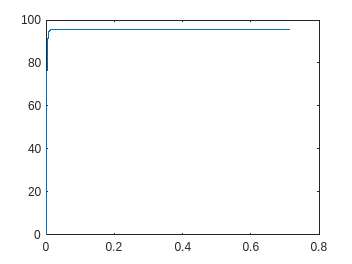


plot(tplt, p1plt/10^5)
hold off

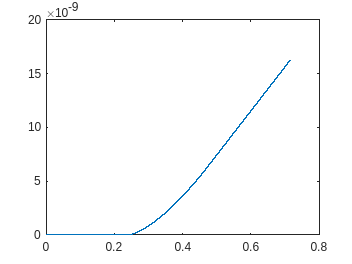

plot(tplt, p2plt/10^5)
hold off

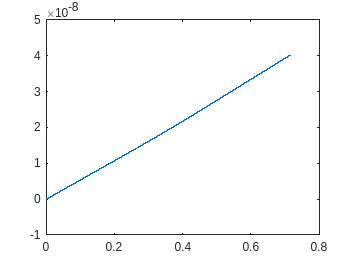

plot(tplt, p3plt/10^5)

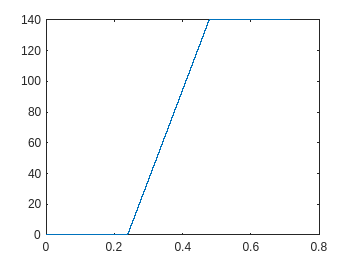

plot(tplt,ps2plt/10^5)

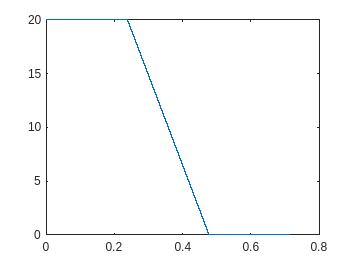

plot(tplt,Ad3plt*10^6)


% 73,8874 